This function gets increasingly oscillatory near the right endpoint.

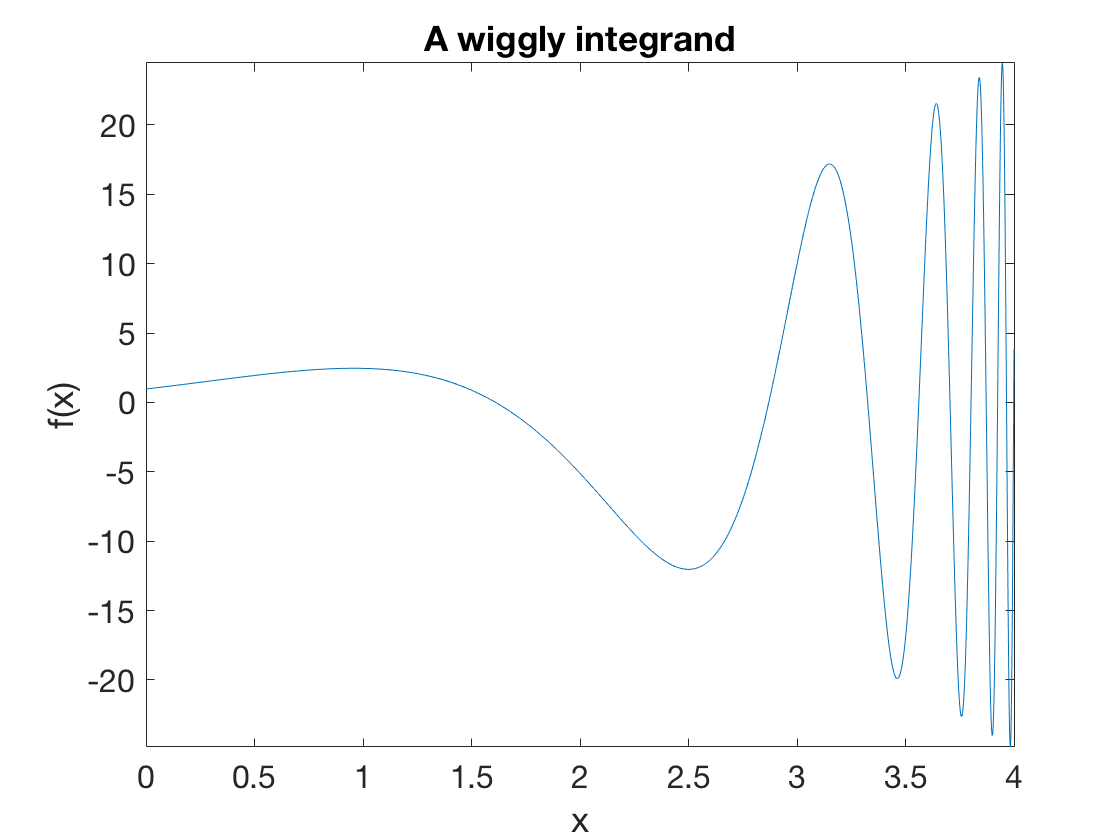

f = @(x) (x+1).^2.*cos((2*x+1)./(x-4.3));
fplot(f,[0 4],2000)
xlabel('x'), ylabel('f(x)')    % ignore this line
title('A wiggly integrand')

Accordingly, the trapezoid rule is more accurate on the left half of the interval than on the right half.

n_ = 50*2.^(0:3)';
T_ = [];
for i = 1:length(n_)
    n = n_(i);
    T_(i,1) = trapezoid(f,0,2,n); 
    T_(i,2) = trapezoid(f,2,4,n);
end

left_val = integral(f,0,2,'abstol',1e-14,'reltol',1e-14);
right_val = integral(f,2,4,'abstol',1e-14,'reltol',1e-14);
table(n_,T_(:,1)-left_val,T_(:,2)-right_val,... 
    'variablenames',{'n','left_error','right_error'})

ans = 4×3 table
        n         left_error     right_error
    __________    ___________    ___________

    5.0000e+01    -2.4911e-03    5.0423e-01 
    1.0000e+02    -6.2271e-04    9.6004e-02 
    2.0000e+02    -1.5568e-04    2.2547e-02 
    4.0000e+02    -3.8919e-05    5.5542e-03 


Both the picture and the numbers suggest that more nodes should be used on the right half of the interval than on the left half.